1. Загрузите данные **ex2data1.txt **из текстового файла.

data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

2. Постройте график, где по осям откладываются оценки по предметам, а точки обозначаются двумя разными маркерами в зависимости от того, поступил ли данный студент в университет или нет.

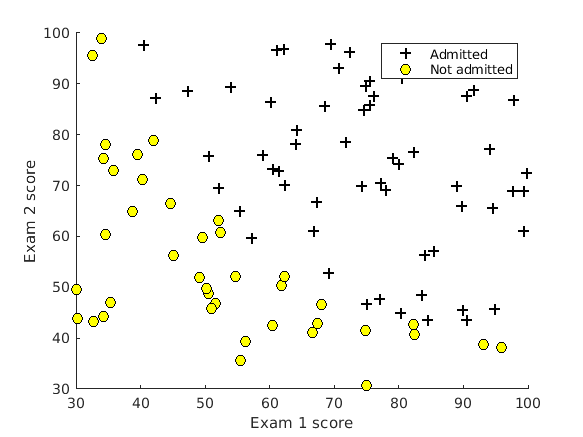

plotData(X, y);

xlabel('Exam 1 score')
ylabel('Exam 2 score')

legend('Admitted', 'Not admitted')

3. Реализуйте функции потерь J(θ) и градиентного спуска для логистической регрессии с использованием векторизации.

X = data(:, [1, 2]); y = data(:, 3);
[m, n] = size(X);

X = [ones(m, 1) X];
theta = zeros(n + 1, 1);
alpha = 0.001;
for iter = 1:1000000
    h = sigmoid(X*theta);
    [j,grad] = costFunction(theta, X, y);
    theta = theta - alpha * grad';
end
theta

theta =   -15.3952
    0.1283
    0.1225


4. Реализуйте другие методы (как минимум 2) оптимизации для реализованной функции стоимости (например, Метод Нелдера — Мида, Алгоритм Бройдена — Флетчера — Гольдфарба — Шанно, генетические методы и т.п.). Разрешается использовать библиотечные реализации методов оптимизации (например, из библиотеки scipy).

5. Реализуйте функцию предсказания вероятности поступления студента в зависимости от значений оценок по экзаменам.

6. Постройте разделяющую прямую, полученную в результате обучения модели. Совместите прямую с графиком из пункта 2.

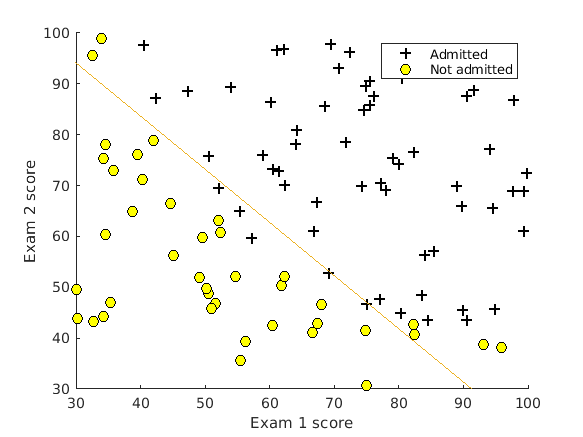

% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

7. Загрузите данные **ex2data2.txt **из текстового файла.

data = load('ex2data2.txt');

8. Постройте график, где по осям откладываются результаты тестов, а точки обозначаются двумя разными маркерами в зависимости от того, прошло ли изделие контроль или нет.

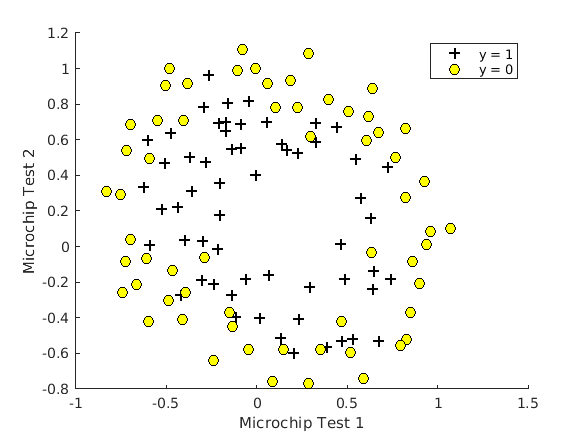

X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

9. Постройте все возможные комбинации признаков x1 (результат первого теста) и x2 (результат второго теста), в которых степень полинома не превышает 6, т.е. 1, x1, x2, x12, x1x2, x22, …, x1x25, x26 (всего 28 комбинаций).

X = mapFeature(X(:,1), X(:,2), 6);

10. Реализуйте L2-регуляризацию для логистической регрессии и обучите ее на расширенном наборе признаков методом градиентного спуска.

theta = zeros(size(X,2), 1);
alpha = 0.01;
lambda = 1;
for iter = 1:10000
    h = sigmoid(X*theta);
    [j,grad] = costFunctionReg(theta, X, y, lambda);
    theta = theta - alpha * grad';
end
theta

theta =     1.0175
    0.4432
    0.9520
   -1.6249
   -0.6214
   -0.9945
    0.0325
   -0.2675
   -0.2672
   -0.1912


12. Реализуйте функцию предсказания вероятности прохождения контроля изделием в зависимости от результатов тестов.

predictReg(theta, 0.54666,0.48757, 6)

ans = logical
   1


predictReg(theta, 0.18376,0.93348, 6)

ans = logical
   0


13. Постройте разделяющую кривую, полученную в результате обучения модели. Совместите прямую с графиком из пункта 7.

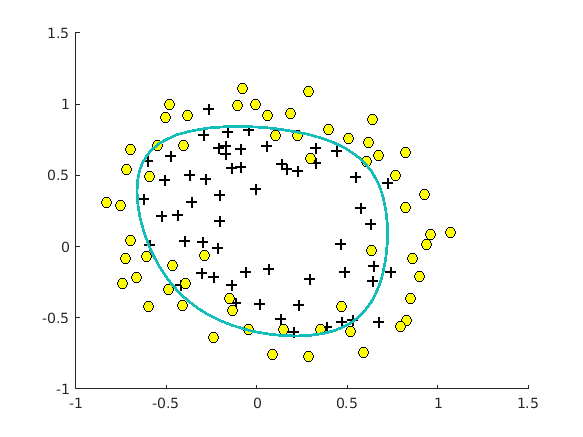

plotDecisionBoundary(theta, X, y, 6);

14. Попробуйте различные значения параметра регуляризации λ. Как выбор данного значения влияет на вид разделяющей кривой? Ответ дайте в виде графиков.

theta = zeros(size(X,2), 1);
lambda = 0;
for iter = 1:10000
    h = sigmoid(X*theta);
    [j,grad] = costFunctionReg(theta, X, y, lambda);
    theta = theta - alpha * grad';
end
plotDecisionBoundary(theta, X, y, 6);
hold on
theta = zeros(size(X,2), 1);
lambda = 1;
for iter = 1:10000
    h = sigmoid(X*theta);
    [j,grad] = costFunctionReg(theta, X, y, lambda);
    theta = theta - alpha * grad';
end
plotDecisionBoundary(theta, X, y, 6);
theta = zeros(size(X,2), 1);
lambda = 10;
for iter = 1:10000
    h = sigmoid(X*theta);
    [j,grad] = costFunctionReg(theta, X, y, lambda);
    theta = theta - alpha * grad';
end
plotDecisionBoundary(theta, X, y, 6);
theta = zeros(size(X,2), 1);
lambda = 100;
for iter = 1:10000
    h = sigmoid(X*theta);
    [j,grad] = costFunctionReg(theta, X, y, lambda);
    theta = theta - alpha * grad';
end
plotDecisionBoundary(theta, X, y, 6);

15. Загрузите данные **ex2data3.mat **из файла.

load('ex3data1.mat');

16. Визуализируйте несколько случайных изображений из набора данных. Визуализация должна содержать каждую цифру как минимум один раз.

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);

displayData(sel);

17-19. Реализуйте бинарный классификатор с помощью логистической регрессии с использованием векторизации (функции потерь и градиентного спуска).

Добавьте L2-регуляризацию к модели.

Реализуйте многоклассовую классификацию по методу “один против всех”.

20. Реализуйте функцию предсказания класса по изображению с использованием обученных классификаторов.

21. Процент правильных классификаций на обучающей выборке должен составлять около 95%.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);
pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);